# Bicycle model Simulink experiment

Doc : https://fr.mathworks.com/help/robotics/ug/plan-path-for-a-bicycle-robot-in-simulink.html

clear; clc;

### Load environment

open_system('pathPlanningBicycleSimulinkModel.slx')

load exampleMaps.mat;
startLoc = [5 5];
startOrient = pi;
goalLoc = [35 22];
chosenMap = complexMap;

### Run model

simulation = sim('pathPlanningBicycleSimulinkModel.slx');

### Visualise everything

#### Define map layout (walls, ...)

map = binaryOccupancyMap(chosenMap)

map =   binaryOccupancyMap with properties:

    GridLocationInWorld: [0 0]
           XWorldLimits: [0 52]
           YWorldLimits: [0 41]
               DataType: 'logical'
           DefaultValue: 0
             Resolution: 1
               GridSize: [41 52]
           XLocalLimits: [0 52]
           YLocalLimits: [0 41]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]


#### Get all robot poses

robotPose = simulation.BicyclePose

robotPose =     5.0000    5.0000    3.1416
    4.9410    5.0193    2.5103
    4.9100    5.0564    2.0223
    4.9002    5.1036    1.5383
    4.9045    5.1415    1.4084
    4.9114    5.1789    1.3777
    4.9206    5.2247    1.3700
    4.9329    5.2846    1.3686
    4.9495    5.3662    1.3751
    4.9660    5.4540    1.4001


#### Print map of movements

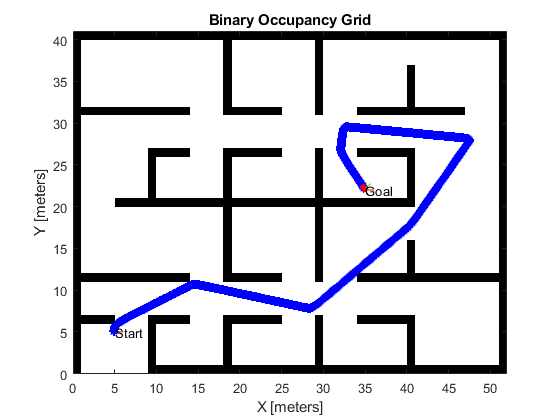

numRobots = size(robotPose, 2) / 3;
thetaIdx = 3;

% Translation
xyz = robotPose;
xyz(:, thetaIdx) = 0;

% Rotation in XYZ euler angles
theta = robotPose(:,thetaIdx);
thetaEuler = zeros(size(robotPose, 1), 3 * size(theta, 2));
thetaEuler(:, end) = theta;

show(map)
hold on;

% Plot Start Location
plotTransforms([startLoc, 0], eul2quat([0, 0, 0]))
text(startLoc(1), startLoc(2), 2, 'Start');

% Plot Goal Location
plotTransforms([goalLoc, 0], eul2quat([0, 0, 0]))
text(goalLoc(1), goalLoc(2), 2, 'Goal');

% Plot Robot's XY locations
plot(robotPose(:, 1), robotPose(:, 2), '*b')

% Plot Robot's pose as it traverses the path
quat = eul2quat(thetaEuler(size(xyz, 1), :), 'xyz');
plotTransforms(xyz(size(xyz, 1),:), quat, 'MeshFilePath',...
    'groundvehicle.stl');

pause(0.01)
hold off;
view([-0.853 90.000])